## Load ECG Data from parent directory

cd ..
clear,clc
load('mitdb_dataset.mat')
cd ./PCA

## Load Noise file, Find R-Peaks, Calculate RR-Intervals

load('em_noise.mat')
numRecords = size(ecg,1);
%numExperiments = 1;
rrInterval = cell(numRecords,1);
rr_tm = cell(numRecords,1);

for i = 1:numRecords
    [~, rr_tm{i,1},~] = pan_tompkin2(ecg{i,1},Fs(i));
    rrInterval{i,1} = zeros(1,length(rr_tm{i,1})-1);
    for z = 1:length(rrInterval{i,1})-1
        rrInterval{i,1}(z) = rr_tm{i,1}(z+1) - rr_tm{i,1}(z);
    end
end

## Noise Generation and Pre-Allocating Variables for Results

Experiments = ["Gaussian12dB","0.1EM","Gaussian6dB","0.2EM","Gaussian2dB","0.3EM"];
windowOptions = 3:36:1200;
k = 1;
window=115;
%
numExperiments = 6;
%numExperiments = length(windowOptions);
numExpRecords = numRecords;
%numExpRecords = 1;
gaussianSNRs = [12 6 2];
EM_scales = [.1 .2 .3];
%snr =  gaussianSNRs(2);
%scale = EM_scales(2);

snr_imp = zeros(numExpRecords,numExperiments);
denoisedSignal2Plot = cell(numExpRecords,numExperiments);
noisySignal2Plot = denoisedSignal2Plot;
varianceExplained = denoisedSignal2Plot;
origSignal2Plot = cell(numExpRecords,1);
sampleRange = 1001:3000;

tic

for i = 1:numExpRecords
    recNum = i; % Can select number between 1 and 23 to access MIT database
    expNum = 1;
    these_rr_ints = rrInterval{recNum,1};
    rPeakStamps = rr_tm{recNum,1};
    ecgTrue = ecg{recNum,1};
    origSignal2Plot{recNum,1} = ecgTrue(sampleRange);


    for j = 1:3
    %for j = 1:numExperiments
        snr = gaussianSNRs(j);
        scale = EM_scales(j);
        %expNum = j;
        %window = windowOptions(j);
        [noisyECG, ~] = createSignalPlusNoise(ecgTrue,snr);
        noisyECG2 = ecgTrue+scale*em_noise;
        [denoisedSignal2Plot{recNum,expNum},snr_imp(recNum,expNum),varianceExplained{recNum,expNum}] = PCA_denoisingMIT(noisyECG,...
            ecgTrue,these_rr_ints,rPeakStamps,window,k,sampleRange);
        noisySignal2Plot{recNum,expNum} = noisyECG(sampleRange);
        expNum=expNum+1;
        
        [denoisedSignal2Plot{recNum,expNum},snr_imp(recNum,expNum),varianceExplained{recNum,expNum}] = PCA_denoisingMIT(noisyECG2,...
            ecgTrue,these_rr_ints,rPeakStamps,window,k,sampleRange);
        noisySignal2Plot{recNum,expNum} = noisyECG2(sampleRange);
        expNum=expNum+1;
    end
end

toc

Elapsed time is 177.808720 seconds.


%expNum = expNum+1;
%[denoisedSignal2Plot{recNum,2},snr_imp(2),varianceExplained{recNum,expNum}] = PCA_denoisingMIT(noisyECG2,ecgTrue,these_rr_ints,rPeakStamps,movWindowSize,k,sampleRange);
%origSignal2Plot{recNum,1} = ecgTrue(sampleRange);
%noisySignal2Plot{recNum,1} = noisyECG(sampleRange);
%noisySignal2Plot{recNum,2} = noisyECG2(sampleRange);

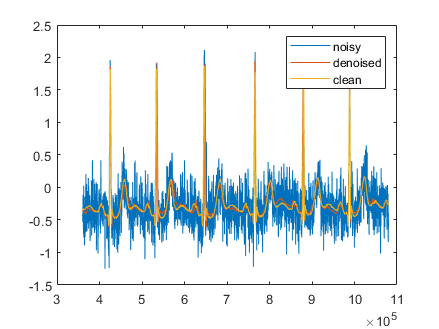


figure
plot(sampleRange.*360, noisySignal2Plot{4,5})
hold on
plot(sampleRange.*360, denoisedSignal2Plot{4,5})
plot(sampleRange.*360 , origSignal2Plot{4,1})
legend('noisy','denoised','clean')

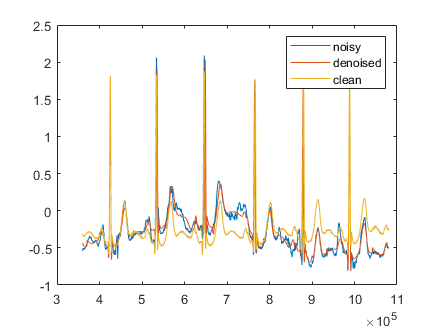

figure
plot(sampleRange.*360, noisySignal2Plot{4,6})
hold on
plot(sampleRange.*360, denoisedSignal2Plot{4,6})
plot(sampleRange.*360 , origSignal2Plot{4,1})
legend('noisy','denoised','clean')